Truncamiento y Redondeo

Serie de Taylor/Maclaunn (a = 0)

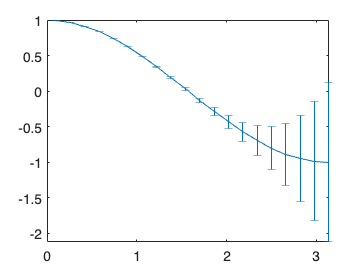

x = linspace(0.1, pi, 20);
aprox = 1-x.^2/2+x.^4/24;
error = cos(x) - aprox;
errorbar(x, cos(x), error);


f(x) = exp(x)

function [fx, iter] = iterExp(x, es, maxit)
    iter = 1;
    fx = 1;
    condition = true;
    while condition
        term = x^iter/factorial(iter);
        fOld = fx;
        fx = fx + term;
        iter = iter + 1;
        condition = abs(fx - fOld/fx) > es && iter<maxit;
    end
end